#  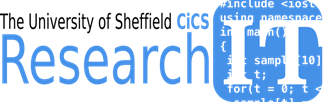                                      

# **Programming with Matlab : Code Testing and Writing Robust Code**

## Outline

- overview

- Verifying Application Behaviour - Testing Frameworks

- Creating Robust Applications - Exception Handling

- Algorithm Devlopment

# Overview

- Code Analyzer

- Debugging

- Profiling and Timing

- Vectorisation

- Memory Management and Preallocation

- Algorithm Devlopment

Provide the tools to develop and maintain high quality software for your research. Properly documented to enable researchers to repeat and reuse your research.

The Matlab workbench and editor already provide many features to make programming much easier, just check the code fragment below. Copy and paste this fragment as a script in the matlab editor.

Observe how the matlab editor highlights warnings and errors on the right hand bar clicking on the individual items shows the warning/error and provides suggestions.

# Verifying Application Behaviour

- Testing Frameworks - The Matlab Unit Testing Framework

- The Test Environment

-         Script Based Testing

-        Function Based Testing

-        AvoidingBugs in Comparisons

- Verifying Behaviour

- Function Handles

- Pre. and Post Test Tasks

# Testing Frameworks - The Matlab Unit Testing Framework 

The idea is that we have now written an algorithm in MATLAB, and before  it is deployed in a real situation, we should take some measures to  ensure that the code is robust and meets its required specifications. In the previous chapter we claimed that the resulting function was robust, flexible and responds correctly to error conditions, but we have not  tested this in any way. In this chapter we will learn how to use the  function-based unit testing framework to write function-based unit tests and formally verify correct behaviour of our algorithm.

A unit test may be regarded as a means of formalising the  specifications that code is required to meet.  Writing and using unit  tests provides several benefits, including:

- early identification of potential problems and bugs in code;

- facilitation of subsequent code changes (i.e. ensuring that code   modification in the future does not alter code correctness);

- greater motivation to modularise code into smaller, individually   testable units;

- clearer documentation of code requirements and specifications.

A simple test should:

- Set up the circumstances under which you want to test the application.

- Call the application.

- Define the expected value.

- Compare the actual and expected behaviors.

In the following example, the function `foo` is expected to return the value `123` when called with inputs π and `42`.

`>> ``x` `=` `pi``;`

`>> ``y` `=` `42``;`

`>> ``actual` `=` `foo``(``x``,``y``)``;`

`>> ``expect` `=` `123``;`

`>> ``isequal``(``actual``,``expect``)`

## `is``*` Functions

MATLAB includes a large number of [`is``*` functions](http://www.mathworks.com/help/releases/R2014b/matlab/ref/is.html) that you can use to check the properties of variables, such as size, type dimensions, and value attributes (real, NaN, integer, alphabetic character, etc.).

Note that if you want to check the equality of two arrays, the `isequal` function checks that the arrays are exactly the same returning a scalar value of either `true` or `false`. Contrast this with the `==`operator, which checks equality of each corresponding element in the arrays.

x = 2:2:6;
y = 2*(1:3);

%TODO use == compare x,y
x==y

ans = 1×3 logical array
   1   1   1



%TODO use isequal compare x,y
isequal(x,y)

ans = logical
   1



z = 2*(1:4)

z =      2     4     6     8


%TODO x==z
%x==z %uncomment to observe effect
%observe what happens for vectors of differing size
isequal(x,z) %isequal returns a value of false because the arrays are not the same.

ans = logical
   0


A formal testing framework should produce either no response, to indicate that the test was passed, or an error, to indicate failure. The `assert` function takes a logical input (or an expression that evaluates to a logical result), and generates an error only if the input is `false`.

actual=57.86

actual = 57.8600

expect=57.86

expect = 57.8600

assert(true) %No response is issued when the input is true.
%assert(false) % An error is generated when the input is false. %un comment to observe effect
assert(isequal(actual,expect)) %Use the assert function to compare the 

%TODO assert true, false and apply to isqual actual,expect
 %No response is issued when the input is true.
 % An error is generated when the input is false.
   %Use the assert function to compare the 
% actual and expected results.

# The Test Environment

## Verifying Application Behaviour with Script Based tests

Function-based unit testing allows MATLAB programmers with experience of writing functions to quickly develop unit tests. The first step in  function-based unit testing is to create the main test function file.  This is a single MATLAB file containing a main function and all the  individual local test functions. The main function must be named using  the word "test" either at the beginning or at the end of the name. This  is not case-sensitive.  For example,

- test_myAlgorithm

- myAlgorithmTest

- TestMyAlgorithm

- testMyAlgorithm

are all valid main test function names. The main function has no input  arguments and returns one output (a test array gathering each of the  individual unit tests into one array). The main test function must  collect all of the local test functions into a test array.  This test  array is generated via a call to the functiontests function, which  assembles the test array using a cell array of function handles to the  local functions in the file.  In turn, a cell array of function handles  to the local functions in the main file is generated using a call to  localfunctions.  In order to be recognised as valid individual unit  tests, local functions must include the case-insensitive word “test” at  the beginning or end of the function name, in exactly the same way that  the main test file must be named in order to be recognised as a valid  test file. The main test file is sometimes referred to as a "test  harness", because it collects together all of the local tests.

A test script is simply a MATLAB script that is divided into sections and uses the `assert` function. 

- Code sections allow you to compile multiple tests into a single file. 

- The section header describes the test. 

- Each section of a test script maintains its own workspace. Thus, in each section, you must define all needed variables.

An example test code for the moon orbitest teast case 

Create two tests to test the function dist.m which computes the distance between two orbiting onbjects

Each test will test a different input file:

  - rocketorbittest.mat

  - moonorbittest.mat

 Test that the file produces the correct distance between the rocket and the body it is orbiting i.e. earth or moon. The test uses the assert with the isequal test to check the validity of the dist

addpath('../matlab_examples/casestudies/mission-moon/code-005-tests')
cd '../matlab_examples/casestudies/mission-moon/code-005-tests/tests'


edit('readconfigtest.m')

%TODO run readconfigtest
readconfigtest  
             
cd '../../../../../presentations'


In order to run each and every section of a test script, use the `runtests` function. If you run the test script as a regular script, any failed tests will produce an error, halting execution. Thus, the remaining tests will not be performed. Whereas, the `runtests` function will move to the next section of the script after an error is encountered so that all the tests run.

cd '../matlab_examples/casestudies/mission-moon/code-005-tests/tests'

%TODO use runtests to run readconfigtest.m assign to  result
result=runtests('readconfigtest.m')

Running readconfigtest

Error occurred in readconfigtest/TestRocketorbitest_mat and it did not run to completion.

    ---------
    Error ID:
    ---------
    'MATLAB:TooManyInputs'

    --------------
    Error Details:
    --------------
    Error using dist.apply
    Too many input arguments.
    
    Error in dist (line 61)
      d = dist.apply(w,varargin{:});
    
    Error in 

result =   1×4 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   2 Passed, 2 Failed, 2 Incomplete.
   0.10199 seconds testing time.



cd '../../../../../presentations'
rmpath('../matlab_examples/casestudies/mission-moon/code-005-tests')

# Avoiding Bugs in Comparisons

Sometimes testing for equality leads to unexpected results due to numerical precision. You will learn how to make your equality tests more robust.


x = 1.0000

x = 1

y =1.0000

y = 1

x==y

ans = logical
   1


%TODO use abs to compare x and y use a tolerance value
abs(x-y)<1e-6


Due to rounding errors, even though the variables `x` and `y` may appear to be equal, they can actually differ in the very last bit of precision when stored in memory. Therefore, when comparing two values, specify a value of tolerance.

# Writing Test Functions

Creating a function-based test file will allow you to generate more flexible and robust tests through the use of verification functions and pre- and post-test tasks. Here you will learn the framework for creating a test function.

The main function must be named using the word "test" either at the  beginning or at the end of the name. This is not case-sensitive.  For  example,

- test_myAlgorithm

- myAlgorithmTest

- TestMyAlgorithm

- testMyAlgorithm

are all valid main test function names. The main function has no input  arguments and returns one output (a test array gathering each of the  individual unit tests into one array). The main test function must  collect all of the local test functions into a test array.  This test  array is generated via a call to the functiontests function, which  assembles the test array using a cell array of function handles to the  local functions in the file.  In turn, a cell array of function handles  to the local functions in the main file is generated using a call to  localfunctions.  In order to be recognised as valid individual unit  tests, local functions must include the case-insensitive word “test” at  the beginning or end of the function name, in exactly the same way that  the main test file must be named in order to be recognised as a valid  test file. The main test file is sometimes referred to as a "test  harness", because it collects together all of the local tests.

Recommended activity: create a new test file for fitQuadModel and name it  test_fitQuadModel. Define the test array output using functiontests and  localfunctions.

## Local Test Functions.

The second step in creating function-based unit tests is to write the local test functions. These are included as local functions in the main  test-generating function. To indicate that a local function should be  used as a local test function, include the case-insensitive word "test"  either at the beginning or at the end of its name. Local test functions  have a fixed interface. Each local test function must accept a single  input argument (a function test case object) and return no outputs. The  MATLAB Unit Testing Framework automatically generates the function test  case object.

A test function follows a specific template:

% function test = mainFunctionName
% 
% test = functiontests(localfunctions);
% 
% end

% function testName1(testcase)
% 
% % code for test 1
% 
% end

% function testName2(testcase)
% 
% % code for test 2
% 
% end

*Each test goes in its own local function.*

For each test:

- Create a local function.

- Name each test function starting or ending with the word "test."

- Pass a single input variable.

You run the test function the same way you run a test script.

`>> ``result` `=` `runtests``(``'``mainFunctionName``'``);`

`Write the rocket test script as a test function`

addpath('../matlab_examples/casestudies/mission-moon/code-005-tests')
cd '../matlab_examples/casestudies/mission-moon/code-005-tests/tests'

edit('readconfigtestfcn.m')

%TODO runtests for readconfigtestfcn

result=runtests('readconfigtestfcn')

Running readconfigtestfcn
....
Done readconfigtestfcn
__________



result =   1×4 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   4 Passed, 0 Failed, 0 Incomplete.
   0.039014 seconds testing time.



cd '../../../../../presentations'
rmpath('../matlab_examples/casestudies/mission-moon/code-005-tests')

# Verifying Behaviour

It can be useful to verify that an application behaves in a certain way, such as generating an error or not generating warnings under specific conditions. In this case, you are testing specifically the application’s behavior rather than the results it returns. You can use test functions to perform more sophisticated tests through qualification functions that are only available for use in the test function framework.

The `Verifiable` class provides a qualification to produce soft-failure conditions. Apart from actions performed for failures, the `Verifiable` class works the same as other `matlab.unittest` qualifications.

Upon a verification failure, the `Verifiable` class informs the testing framework of the failure, including all diagnostic information associated with the failure, but continues to execute the currently running test without throwing an `MException`. This is most useful when a failure at the verification point is not fatal to the remaining test content.

## Verification Functions

There are many qualification functions available in the function-based testing framework. The following Verification functions available for function-based tests

`verifyClass`

`verifyEmpty`

`verifyEqual`

`verifyError`

`verifyFail`

`verifyFalse`

`verifyGreaterThan`

`verifyGreaterThanOrEqual`

`verifyInstanceOf`

`verifyLength`

`verifyLessThan`

`verifyLessThanOrEqual`

`verifyMatches`

`verifyNotEmpty`

`verifyNotEqual`

`verifyNotSameHandle`

`verifyNumElements`

`verifyReturnsTrue`

`verifySameHandle`

`verifySize`

`verifySubstring`

`verifyThat`

`verifyTrue`

`verifyWarning`

`verifyWarningFree`

The local test functions have a single input, named `testcase` in the example below. Your test code should use it as the first input to the verification function.

addpath('../matlab_examples/casestudies/mission-moon/code-005-tests')
cd '../matlab_examples/casestudies/mission-moon/code-005-tests/tests'

edit('readconfigvertestfcn.m')


result = runtests('readconfigvertestfcn'); 

Running readconfigvertestfcn
....
Done readconfigvertestfcn
__________




%MException.last.identifier  %can only be called from command prompt

%result=runtests('readconfigvertestfcn')
cd '../../../../../presentations'
rmpath('../matlab_examples/casestudies/mission-moon/code-005-tests')

# Function Handles

You can use a function handle to store a command as a variable, which can then be passed as an input to a function.

construct a function handle by preceding the function name with an `@`sign.

h = @sin;

call the function handle in the same way that you would call the function directly.

h(0)
h(pi/2)


Some functions, such as `integral`, require an input function. In this case, you give the function handle as an input.

integral(h,0,pi)
integral(@log,1,2)

## Optimisation Example

 use the `fzero` function to find a zero crossing value of `fcnName` with a starting value of `xStart`.

`>> ``x` `=` `fzero``(``@``fcnName``,``xStart``)`

Create a variable named `x0` which contains the zero crossing value of the `humps` function with a starting value of `0`.

x = -1:0.01:1;
plot(x,humps(x))
x0 = fzero(@humps,0)

use `fminbnd` to find the minimum value within a given range. Call `fminbnd` with three inputs:

- a function handle to `fcnName`

- a lower bound scalar value

- an upper bound scalar value

`>> ``x` `=` `fminbnd``(``@``fcnName``,``lowerBnd``,``upperBnd``)`

Create a variable named `xMin` which contains the x-value for the local minimum value of `humps` that is near 0.6.

xMin=fminbnd(@humps,0.4,0.7)

## Anonymous Functions

A  function handle is a variable containing a reference to a function. Using a function handle  reduces the problem of calling a function to that of accessing a  variable. The function handle contains all information necessary to  evaluate the function at given input arguments. For further information  on function handles, see MATLAB -> Language Fundamentals -> Data  Types -> Function Handles.

You can use anonymous functions to create simple functions without creating a code file the example below shows an anonymous function definition for a polynomial

modelFun = @(c, x1, x2) c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
                        c(5)*x2.^2 + c(6)*x1.*x2;
modelCoeffs=rand(6,1);
% It's helpful to draw the analogy with the mathematical notation:
% f(c, x1, x2) = c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
%                       c(5)*x2.^2 + c(6)*x1.*x2
% The only difference between the mathematical notation and the function
% handle definition is the "@" symbol, signifying to MATLAB that a function
% handle is being created.
% This function handle can now be evaluated at any point or any series of
% points, just like a normal mathematical function. For example:
disp(modelFun(modelCoeffs, 0, 0)) % Evaluates the model function at (0,0).

An anonymous function to compute distance from earth in km

cd '../matlab_examples/casestudies/mission-moon/code-005-tests'
load('rocketorbittest.mat');
de = @(x,y) dist(x,y,state.xe,state.ye)/1000;

distfromearthkm=de(state.x,state.y)
cd '../../../../presentations'

## Commands as function Inputs

Some verification functions, such as `verifyTrue` or `verifyEqual`, take values as inputs.

However, other functions such as `verifyError` and `verifyWarningFree`, require a command as input.

You can use a function handle to store a command as a variable to pass as input to a function. Use the following syntax:

`x` `=` `@``()` `expression`

The function `verifyWarningFree` tests the command to ensure that there is no warning displayed.

% function testNoWarning(testcase)
% cmd = @() sqrt(9);
% verifyWarningFree(testcase,cmd)
% end

Similarly, the `verifyError` and `verifyWarning` functions determine if the command produced an error or warning and allow you to compare it with an identifier. You can find the identifier of the last error displayed using the `MException.last.identifier` command.

%enter the following into the matlab commandline
%sqrt('hello')
%MException.last.identifier

The basic syntax for using the `verifyError` function is:

`verifyError``(``testcase``,``cmd``,``identifier``)`

- `testcase` - the local function input is always the first input variable to the `verify``*` functions

- `cmd` - the anonymous function that represents the command to be checked

- `identifier` - the error identifier, specified as a string

The function `verifyError` tests the command to ensure that an error is shown.

% function testNumericInput(testcase)
% cmd = @() sqrt('hello');
% verifyError(testcase,cmd,'MATLAB:UndefinedFunction')
% end

Return to the section  above for the Verification Functions. Uncomment the last test in the `readconfigvertestfcn.m` file for the mission-moon case study. It should use the `verifyError` function. Test the call to load with an input file name that is not recognized. Check that the proper error is returned. The identifier is specified by `errorMessage` in the template file.

## Adding Pre and Post Test Tasks

## Setup and Teardown Functions.

It can be useful to define tasks that should be performed immediately before and after running the actual tests defined in your test code. For example, if you keep the test code and the application in separate locations, the location of the application code can be added to the MATLAB path for the tests to successfully run.

Before running  tests, it is often required to change directory or load some data from a MAT-file. We may also require a certain system state to be established  before running a test.

For example, we may require a figure to be open  before testing a graphical function, or we might need to set a specific  starting point in a random number stream in order to test a Monte Carlo  simulation.

Setup and teardown code, 

also referred to as test fixture  functions, set up the pre-test state of the system and return it to the  original state after running the test. 

This is important because the  results of tests should be completely reproducible, and we also do not  want to interfere with existing settings or the existing system state.  Anything that is modified in the setup code before running the tests  should be "undone" in the teardown code. 

There are two types of these  functions:

 file fixture functions that run once per test file, and fresh fixture functions that run before and after each local test function.  

As with local test functions, the only input to test fixture functions  is a function test case object, which is automatically passed to each  function by the unit test framework. The function test case object is a  means to pass information between setup functions, local test functions, and teardown functions. By default, every test case object has a  TestData property which is a 1x1 struct. This allows easy addition of  fields and data to the TestData property, which updates the function  test case object. Typical uses for this test data include paths and  graphics handles. File fixture functions are used to share setup and  teardown functions across all the tests in a file. The names for the  file fixture functions must be setupOnce and teardownOnce, respectively. These functions execute a single time for each file. On the other hand, fresh fixture functions are used to set up and tear down states for  each local test function. The names for these fresh fixture functions  must be setup and teardown, respectively.

You can add pre- and post-test tasks to your testing function by adding functions with the special names `setupOnce` and `teardownOnce` which have the same signature as the other test functions.

A variation of  the `readconfigtestfcn` file is made by adding two functions, this iis saved as `readconfigtestfcn2` .

- The pre-test function should:

- Create a variable named `tol` that can be shared between all the local functions with a value of `1e-4` and use it in the relevant test functions.

- Create a variables named testcase.TestData.moondat and testcase.TestData.rocketdat

- Add the `source` folder to the path using the `addpath` function. The `source` folder is in the current folder.

- The post-test function should remove the `source` path using the `rmpath` function.

Use `testcase` as the input variable for both functions.

addpath('../matlab_examples/casestudies/mission-moon/code-005-tests')
cd '../matlab_examples/casestudies/mission-moon/code-005-tests/tests'

edit('readconfigvertest2fcn.m')


result = runtests('readconfigvertest2fcn'); 

Running readconfigvertest2fcn
....
Done readconfigvertest2fcn
__________





%result=runtests('readconfigvertestfcn')
cd '../../../../../presentations'
rmpath('../matlab_examples/casestudies/mission-moon/code-005-tests')

# Creating Robust Applications

- Generating Custom Warnings and Errors

- Validating Function Inputs

- Setting Default Input Values

- Creating Flexible Inerfaces

- Error Handling with try-catch

## Generating Custom Warnings and Errors

A program should generate clear error or warning messages when something goes wrong. Consider the following function which calculates the area of a triangle given a vector containing the length of the sides.

% function a = triangleArea(s)
% p = (s(1) + s(2) + s(3))/2;
% a = sqrt(p*(p-s(1)*(p-s(2))*(p-s(3))));
% end

If a user called the function with 2 elements it should report an informative message, for example

`>> area` `=` `triangleArea``([``2` `3``])``;` 

`The input should be vector of three elements each representing the length of a side.`

How can we generate custom warning and error messages

- Warnings represent conditions from which the program can recover, but the user may still want to know about them. 

- Errors, on the other hand, terminate the execution of the program.

You can use the `warning` and `error` functions to generate custom warnings and errors.

`warning``('MyProject:ValueOutOfRange',``'The value must be between 1 and 10.'``)`

**The first message is an Identifier**

- Hidden from the user

- Contains components separated by **':'**

- First component is typically the name of the application

- Second component identifies the condition for the error or the warning

**The second message is an Error or warning message**

- This message is displayed to the user

- Errors are displayed in red and warnings in orange

Note the colour of the warning and error messages below

%%TODO replace with equivalent for update function (don't forget to cd to case study directory) updatestate and playrocket2themoon

%error('MyProject:invalidValue', 'The value must be numeric.');  %remove comment and run section to observe behaviour
%%TODO replace with equivalent for update function (don't forget to cd to case study directory)

warning('MyProject:ValueOutOfRange',...
    'The value must be between 1 and 10.')

## Validating Function Inputs

Consider the function `getElevations` which is declared as shown below:

`function` `[``elv``,``t``]` `=` `getElevations``(``tstart``,``tspan``,``dt``,``file``,` `obslocation``,``doplot``)`

*Function declaration*

The input `obslocation` is expected to be a vector containing three elements representing the latitude, longitude, and altitude of the observer. What happens when the input corresponding to `obslocation` contains only two elements instead of three?

`>> ``[``elevation``,``t``]` `=` `getElevations``(``'11/24/2014'``,``days``(``1``)``, ``minutes``(``1``)``,``'iss.txt'``,``[``42` `-71``]``,``true``)`

*Function call*

The function execution continues until the third element of `obslocation` is referenced. At this point, MATLAB generates an error message.

These errors can be caught early in the program execution and provide better error messages by validating the inputs.

The MATLAB language provides [several functions](http://www.mathworks.com/help/matlab/ref/is.html) for validating the attributes of a variable. These function names typically start with the word `is`. Common attributes to check are: datatype, dimension, and range of values.

You can use these functions, such as `isscalar` or `isnumeric`, to check various attributes of a variable. If the attributes are not as expected, you can generate custom error messages.

For example 

%%TODO replace with equivalent for grave accell function (don't forget to cd to case study directory)

%int = calculateInterest(500,[2 4],0.08)


% function interest = calculateInterest(p,n,r)
% if ~isscalar(n)
%     error('calcInt:invalidDuration',...
%     'The duration should be a scalar.')
% end
% if r < 0
%     error('calcInt:invalidRate',...
%     'The rate should be non negative.')
% end
% 
% end

Often, you might want to check multiple attributes of a given input. Instead of checking each attribute using a separate `if`-statement, you can use the compact syntax of the function `validateattributes`.

`validateattributes``(name,``class``,``attributes``)``;` 

**name: Variable Name**

- Name of the variable

**class: Class of the variable**

- Should be a cell array containing strings

- Typical examples: `{``'double'``}`, `{``'cell'``}`, `{``'numeric'``}`, etc.

**attributes: Attributes of the variable**

- Should be a cell array containing the list of attributes and their expected values

- Typical examples: `{``'vector'``}`, `{``'nonempty'``}`, `{``'scalar'``,``'>'``,``10``}`, etc.

%%TODO replace with equivalent for grave accell function (don't forget to cd to case study directory)
%int = calculateInterest(500,[2 4],-0.08)

% function interest = calculateInterest(p,n,r)
% validateattributes('r',{'numeric'},...
%     {'scalar','>=',0})
% end

## Setting Default Input Values

Consider the function `getElevations` which has multiple inputs:

`function` `[``elv``,``t``]` `=` `getElevations``(``tstart``,``tspan``,``dt``,``file``,``...`

    `obslocation``,``doplot``)`

*Function declaration*

You can enhance the usability of the function by allowing the user to provide only a subset of the input arguments:

`[``elv``,``t``]` `=` `getElevations``([]``,``days``(``1``)``,``minutes``(``1``)``,``'iss.txt'``)`

*Function call*

In the function call above, an empty array `[]` is passed in place of the starting time `tstart` and no inputs are passed corresponding to the input arguments `obslocation` and `doplot`. 

You can assign default values to the inputs that are not provided by the user. This allows the user to call the function without explicitly passing every input parameter.

## Setting Default Input Values - Missing Input Arguments

To check if all the inputs were provided in the function call, you can use the function `nargin`. When called within the function body, `nargin` returns the number of inputs that were passed when the function was called.

[`nargin`](http://www.mathworks.com/help/matlab/ref/nargin.html)

[varargin](https://uk.mathworks.com/help/matlab/ref/varargin.html)

*Number of input arguments*

The following function calculates the interest earned given the principal, the rate of interest, and the time duration. The user can also specify whether the interest is simple or compounded. 

Notice that the code uses the function `nargin` to check whether the fourth input argument is provided. It assigns a default value if the input is not provided.


%interest = calcInterest(500,2,1,'compounded')
% interest = calcInterest(500,2,1)
%or

%

% function int = calcInterest(p,n,r,type)
% if nargin < 4
%     type = 'simple';
% end
% if strcmp(type,'simple')
%     int = p*n*r/100;
% else
%     int = p*(1+r/100)^n - p;
% end

MATLAB assigns function inputs in order. Consider the function declaration and the function call shown below.

How can you allow the user to specify `type` without specifying `r`? A common way is to use an empty array `[]`. 

- In the function body - check if the input is empty using the function `isempty`. If it is empty, assign a default value.

- In the function call - use an empty array `[]` instead of the input value.

% int = calcInterest(500,2,[],'compounded')
% 
% function int = calcInterest(p,n,r,type)
% if isempty(r)
%     r = 1;
% end
% end

Check the example mean3 in the folder matlab_examples/usingmatlab/basic_scripts

edit('../matlab_examples/usingmatlab/basics_scripts/mean3.m')

## Variable Length Input Argument List

Every input argument in the function call is mapped to a single variable in the function definition. However, you can map multiple input arguments to a single input variable `varargin` in the function definition.

[varargin](https://uk.mathworks.com/help/matlab/ref/varargin.html)

•nargin –number of input arguments

•varargin –cell array of input arguments

•varargout –cell array of output arguments

% function [varargout] = mean3(varargin)
% % MEAN : Calculate the mean value.
% % For vectors: returns a value.
% % For matrices: returns the mean value of each column.
%     for ii = 1:nargin 
%         %ii
%       x=varargin{ii};
%        [ m , n ] = size ( x );
%        if m == 1
%          m = n ;
%     end 
%       varargout(ii)={sum(x)/m};
%     end
% end

% analyzeAndPlot(time,position,'LineWidth',3, 'Color','r')
% 
% function analyzeAndPlot(x,y,varargin)
%     
%     ...
%         
% end

Notice that `varargin` is a cell array. Starting with the third input, each input is assigned to a separate cell of `varargin`.

The contents of `varargin` can be passed to other MATLAB functions such as `plot`.

edit('../matlab_examples/usingmatlab/basics_scripts/mean3.m')

% analyzeAndPlot(time,position,'LineWidth',3, 'Color','r')
% 
% function analyzeAndPlot(x,y,varargin)
% .
% .
% plot(x,y,varargin{:});
%end


# Exception Handling

A program can generate an error for a variety of reasons, such as incorrect inputs, missing data files, etc. 

You can try to check the conditions which lead to these errors and generate custom error messages if a condition holds. However, it is often not practical and sometimes not possible to check for every condition that might lead to an error.

So, what happens when an erroneous MATLAB command is executed?

- A MATLAB generated error message is displayed.

- The program execution stops.

Sometimes, it is useful to avoid halting the execution after an error is generated. The program can then identify the type of the error that was generated and try to recover.

This can be done using a `try``-``catch` construct

**try … catch construct**

•This is Matlab’s version of error trapping mechanism.

•Syntax:

•  try, 

•     *statement,*   

•  catch, 

•     *statement**,* 

•    end

•When an error occurs within the try-catch block the control transfers to the catch-end block. The function lasterr can than be invoked to see what the error was.

## The MException Object

In order to take appropriate actions after a run-time error is generated, it is important to identify the type of the error that was generated.

Error information in MATLAB is stored in a specialized datatype called an `MException` object.

An `MException` object is generated when MATLAB encounters an erroneous command.

`>> ``x` `=` `sin``(``'Hello'``)``;`

Normally you do not see these variables, nor do you typically need to create one. You can access the `MException` object for the last error that occurred using the command:

`>> ``MException``.``last`

An `MException` object is also generated for the user generated error messages: 

`>> ``err` `=` `error``(``'MyApp:BadThing'``,``'A bad thing happened')`

## The try-catch Construct

The try-catch construct provides a way to obtain useful information about the error after the erroneous command is executed.

This special programming construct attempts to run the code within the try block. If an error condition occurs, then the execution is interrupted and switched immediately into the catch block.

`try`

`% Attempt code`

`catch` `mexc`

`% Backup case – something went wrong`

`% An MException object called mexc now exists`

`end`

You can provide the name of a variable after the keyword `catch` (`mexc` in the above example). If an exception occurs in the `try` block, information about it will be captured in the `MException` object with the given name. You can use this variable in the catch block to diagnose the problem and respond appropriately.

If an error is generated in the `try` block the program can then proceed in one of the following ways in the `catch` block:

- Try to recover from the error and continue execution.

- Provide a customized error message and halt the execution.

%simple example write example for moon orbit test

% % Plot result
% if doplot
%     figure
% 
%     % TODO: Run the following command in a try block.
%     % Catch the error and display the 'message' from the
%     % exception object using the function 'warning'.
% 
%     try
%         plot(t,elv,varargin{:})
%     catch MExp
%         warning(MExp.message);
%         plot(t,elv,'k-');
%     end
% end




# Algorithm Development Review - A Case Study

We are now happy writing scripts to organise and collect sequences of  MATLAB commands, but these become increasingly difficult to manage as  the complexity of our algorithms grows. Moreover, a common requirement  is to run scripts repeatedly using different values for certain  parameters within the script. Functions are a more effective programming construct for managing these issues. In this chapter we will learn how  to develop and structure an algorithm for performing simple  preprocessing, model fitting and visualisation. The important concept  here is how to modularise code so that it becomes reusable,  maintainable, flexible and robust.

## Linear Regression Models.

The main example in this chapter is developing an algorithm to perform data preprocessing,  fitting and visualisation. We will use a linear regression model with  variables chosen from the biomedical data discussed in the first chapter of the course. The examples are fairly simple, but if attendees are  unfamiliar with regression, the concepts can be explained in terms of  inputs and outputs. For example, we have an input variable (e.g. Age)  and we would like to model the dependency of an output variable (e.g.  PulsePressure) on the input. It's easier to gather the commands in these sections into a single script, which can then be run section by section and then eventually converted into a properly structured function by  the end of the chapter.

addpath('../matlab_examples/casestudies/health/')
% Visualise the dependency of pulse pressure on age.
load('S02_MedData.mat')
x = MedData.Age;
y = MedData.BPDiff;
figure
scatter(x, y, 'bx')
xlabel('Age')
ylabel('Pulse Pressure')
title('\bfPulse Pressure vs. Age')

% This dependency looks as if it could be modelled using a quadratic curve
% (i.e. using a model of the form PP ~ C0 + C1*Age + C2*Age.^2, where the
% coefficients C0, C1 and C2 are unknown and to be determined).

## Matrix Equations.

Formulating a linear  regression model leads to a system of linear equations A*x = b for the  unknown vector of coefficients x. The design matrix A comprises the  model terms, and the vector b is the data to be modelled (in this  example, the vector of pulse pressure observations). Note carefully that solving such linear systems is a matrix operation, and so any missing  values contained in the data must be dealt with in some way before  attempting to solve the system. (High-level functionality in Statistics  Toolbox can remove missing observations automatically before fitting,  but here we use a core MATLAB solution.)

% Set up the system of equations for fitting a model to the pulse pressure
% data.
missingIdx = isnan(x) | isnan(y);
xClean = x(~missingIdx);
yClean = y(~missingIdx);
designMat = [ones(size(xClean)), xClean, xClean.^2];


## Slash and Backslash.

The least-squares  solution of the system A*x = b in MATLAB is given by x = A\b. If the  system is formulated as x*A = b, then its solution is x = b/A.

% Solve the linear system to find the best-fit coefficients for modelling
% pulse pressure as a quadratic function of age.
modelCoeffs = designMat\yClean;

% Compute the fitted model.
pulseModel = designMat*modelCoeffs;

% Visualise the results.
hold on
plot(xClean, pulseModel, 'r*')
hold off


## Matrix and Array Operators.

Note that in the  above computations we have used the operators * and \. A complete list  of matrix, array and logical operators is available by entering the  command >> doc ops.

doc ops
% It's useful to show this list at this point to point people in the right
% direction for discovering matrix and array operators.

## Generalising the Model.

We now have an  algorithm for fitting a one-dimensional quadratic model to our data. We  would like to generalise this to fit a two-dimensional quadratic surface to a single response variable given two input variables. For example,  we might be interested in predicting a person's weight given knowledge  of their height and waist measurements. We will follow similar steps to  preprocess and clean the data before fitting.

% Extract input variables.
x1 = MedData.Height;
x2 = MedData.Waist;

% Extract output variable.
y = MedData.Weight;

% Clean the data.
missingIdx = isnan(x1) | isnan(x2) | isnan(y);
x1Clean = x1(~missingIdx);
x2Clean = x2(~missingIdx);
yClean = y(~missingIdx);

% Formulate the system of linear equations.
designMat = [ones(size(x1Clean)), x1Clean, x2Clean, x1Clean.^2, ...
             x2Clean.^2, x1Clean.*x2Clean];

% Solve the system.
modelCoeffs = designMat\yClean;

## Function Handles.

Now that we have the second set of model coefficients for the 2D quadratic model, we would like to  visualise the fitted results. To do this, we need to substitute the  model coefficients into the model equation. One way to achieve this is  to use a function handle, which is a variable containing a reference to a function. Using a function handle reduces the problem of calling a  function to that of accessing a variable. The function handle contains  all information necessary to evaluate the function at given input  arguments. For further information on function handles, see MATLAB -> Language Fundamentals -> Data Types -> Function Handles.

modelFun = @(c, x1, x2) c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
                        c(5)*x2.^2 + c(6)*x1.*x2;
% It's helpful to draw the analogy with the mathematical notation:
% f(c, x1, x2) = c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
%                       c(5)*x2.^2 + c(6)*x1.*x2
% The only difference between the mathematical notation and the function
% handle definition is the "@" symbol, signifying to MATLAB that a function
% handle is being created.
% This function handle can now be evaluated at any point or any series of
% points, just like a normal mathematical function. For example:
disp(modelFun(modelCoeffs, 0, 0)) % Evaluates the model function at (0,0).

## Creating Equally-Spaced Vectors.

At this  point, we are ready to visualise our quadratic surface. In MATLAB,  surface plots can be created using a fairly straightforward step-by-step procedure. The first step of this process is to create equally-spaced  vectors of points of "x" and "y" data (the data forming the horizontal  plane). To achieve this, we could use either the colon operator (:) or  the LINSPACE function.

x1Vec = linspace(min(x1Clean), max(x1Clean));
x2Vec = linspace(min(x2Clean), max(x2Clean));
% Note that 100 points in the vector is the default. The number of points
% is optional and can be specified as the third input argument to LINSPACE.

## Making Grids.

The second step in the  procedure is to create matrices containing the coordinates of all grid  points in the lattice. This can be achieved using MESHGRID.

[X1Grid, X2Grid] = meshgrid(x1Vec, x2Vec);
% X1Grid contains all the "x" coordinates of all the lattice points.
% X2Grid contains all the "y" coordinates of all the lattice points.

% Now that we have all lattice points, our surface function can be
% evaluated over the lattice using the function handle defined above.
YGrid = modelFun(modelCoeffs, X1Grid, X2Grid);

## Surface Plots.

Finally, we can visualise the  surface. The basic function here is SURF, into which we provide the  three matrices of surface data (the two coordinate matrices and the  values of the surface function over the lattice).

figure; surf(X1Grid, X2Grid, YGrid)
% We can customise this display by specifying name-value pairs.
surf(X1Grid, X2Grid, YGrid, 'FaceColor', 'interp', 'EdgeAlpha', 0)
% This removes gridlines and uses interpolated shading for the surface,
% instead of colouring each patch a uniform colour.

% View the original data.
hold on
plot3(x1Clean, x2Clean, yClean, 'kx')
xlabel('Height (cm)')
ylabel('Waist (cm)')
zlabel('Weight (kg)')
title('\bfModel for Weight vs. Height and Waist')

% Other 3D visualisation functions can be found in the Plot Gallery.

## Creating a Function.

At this point, we now  have a script which we can run to perform our data clean-up, model  fitting and visualisation. However, it is not straightforward to apply  the algorithms in our script to another set of data. The next step in  modularising our code is to create a function to automate the tasks or  subtasks represented in our current script. Functions are created in  text files with the .m extension, just like script files. However,  functions must begin with a function declaration of the form: function  [out1, out2, ...] = function_name(in1, in2, ...) The keyword "function"  must be the first non-comment code in the file. Syntax for calling  user-defined functions is identical to that used for calling existing  MATLAB functions.

% Recommended activity: create a new function "fitQuadModel" with the
% following declaration line:
% function [modelCoeffs, fh] = fitQuadModel(X, y, showplot)
%
% See the file F02_fitQuadModel_001.

## Workspaces.

Functions operate within their  own function workspace, which is separate from the base workspace  accessed at the prompt or from within scripts. If a function calls  another function, each maintains its own separate workspace. Once a  function has completed, its workspace is destroyed. Instructors may wish to demonstrate the concept of separate workspaces by setting  breakpoints and entering debug mode.

## Local Functions.

There may be times when we wish to outsource certain tasks in a function to  another function. For example, if we think about our algorithm at a  high-level, we are performing three distinct tasks: * we are cleaning up the data by removing NaNs; * we are performing the model fitting; * we  are visualising the results of the fitted model.

We are performing these three tasks on two distinct sets of data. One possibility for  structuring our main function is to have three local functions defined  inside, each of which represents one of the three tasks above. This  enables us to reuse the same function for multiple different sets of  data.